# Laboratorium 2

## Część III – MATLAB jako środowisko programistyczne (ćwiczenia)

## 1. Zadania

### 1.1 A)

Utwórz m-skrypt wczytujący dane z pliku `daneP``.``csv` a następnie realizującego wizualizację danych na wykresie typu `plot` (każda zmienna na osobnym wykresie). Dodaj do każdego wykresu osobny tytuł.

`- `Wskazówka: użyj import wizarda do importu danych, następnie wygeneruj m-funkcję do importu danych i wykorzystaj ją w swoim m-skrypcie

### 1.2 B)

Z zaimportowanych danych wybierz taki fragment, na którym widoczny jest sygnał okresowy. Utwórz nową zmienną zawierającą wybrany fragment sygnału i zwizualizuj ją na osobnym oknie wykresu.

`-` Wskazówka: Przyglądnij się wykresowi każdej składowej i wybierz taką, na której okresowość jestnajlepiej widoczna. Następnie, przy pomocy indeksowania, wybierz  fragment pomijając zakłócenia na początku i na końcu sygnału.

### 1.3 C)

Z wybranego fragmentu sygnału, usuń trend poprzez dopasowanie krzywej wielomianowej. Dobierz stopień wielomianu jak najmniejszego stopnia przy zachowaniu jak najmniejszego błędu dopasowania (funkcja `norm`). Do wykresu z poprzedniego punktu dodaj linię dopasowanego trendu (inny kolor). Utwórz nowy wykres zawierający sygnał z usuniętym trendem.

`-` Wskazówka – możesz zrealizować dopasowanie przy pomocy narzędzia Basic Fitting Tool, a następnie wygenerować m-kod i wybrać z niego potrzebne fragmenty analizy sygnału.

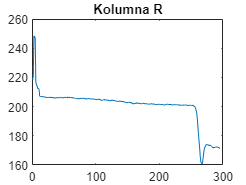

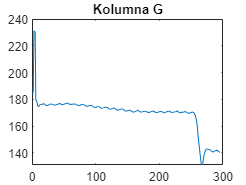

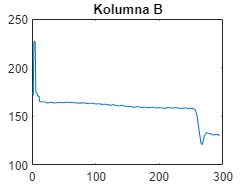

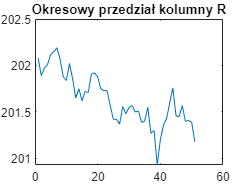

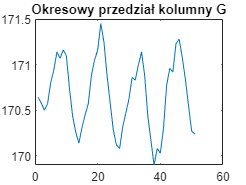

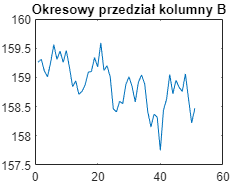

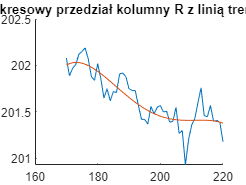

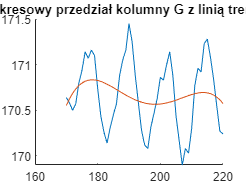

m_plik

### 1.4 D)

Znajdź częstotliwość charakterystyczną sygnału. Sformatuj wykres dodając do niego w sposób programowy: opisy osi x,y i tytuł wykresu. Dodaj do wykresu punkt w miejscu maksimum (częstotliwość charakterystyczna) oraz opis informujący o wartości częstotliwości tego maksimum.

`-` Wskazówka: użyj funkcji `fft` (patrz przykład w dokumentacji) z częstotliwością próbkowania odczytaną z pliku `daneP.csv`

`-` Aby dodać do wykresu opis wykorzystaj funkcję `text` oraz sformatuj tekst przy pomocy funkcji `sprintf`.

Gotowy rezultat powinien wyglądać podobnie jak wykres przedstawiony poniżej.

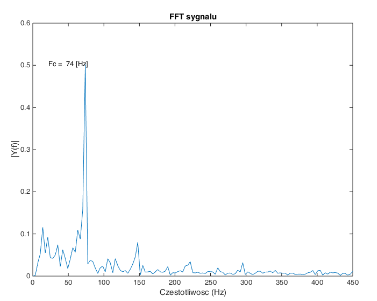

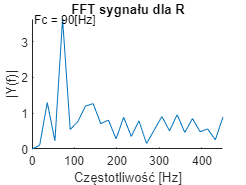

f = 900;

R_fft = abs(fft(R_ntrend));
G_fft = abs(fft(G_ntrend));
B_fft = abs(fft(B_ntrend));

m = length(R_ntrend);

fq = (0 :m/2 + (m/2 - 1)) * f/(m - 1);

figure

hold on

plot(abs(fq), (R_fft))

[R_max, index1] = max(R_fft);

txt1 = "Fc = " + string(index1 * f/(m - 1)) + "[Hz]";

text(index1, R_max, txt1, FontSize=9)

title('FFT sygnału dla R')
xlabel("Częstotliwość [Hz]")
ylabel("|Y(f)|")
axis([0 450 0 inf])

hold off


figure

hold on

plot(abs(fq), (G_fft))

[G_max, index2] = max(G_fft);

txt2 =  "Fc = " + string(index2 * f/(m - 1)) + "[Hz]"

txt2 = "Fc = 90[Hz]"

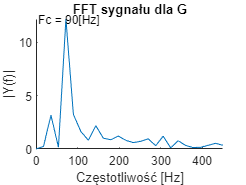


text(index2, G_max, txt2, FontSize=9)

title('FFT sygnału dla G')
xlabel("Częstotliwość [Hz]")
ylabel("|Y(f)|")
axis([0 450 0 inf])

hold off


figure

hold on

plot(abs(fq), (B_fft))

[B_max, index3] = max(B_fft);

txt3 =  "Fc = " + string(index3 * f/(m - 1)) + "[Hz]"

txt3 = "Fc = 90[Hz]"

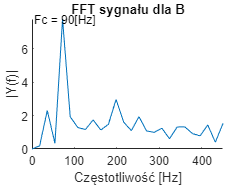


text(index3, B_max, txt3, FontSize=9)

title('FFT sygnału dla B') 
xlabel("Częstotliwość [Hz]")
ylabel("|Y(f)|")
axis([0 450 0 inf])

hold off

## Część IV – MATLAB typy danych (ćwiczenia)

## 2 Zadania

### 2.1 A)

Przy pomocy polecenia `randn` wygeneruj tablicę 3x3 liczb pseudolosowych `R` o rozkładzie normalnym (średnia 0 i odchylenie standardowe). Następnie utwórz zmienną `A` jako typ UINT32, zawierającą liczbę 100. Pomnóż zmienną `R` przez `A`, odpowiednio dostosowując typy danych. Rezultat (zmienna `B`) powinna być typu UINT32. Zwróć uwagę czy rezultaty mnożenia są poprawne ! W sprawozdaniu zanotuj liczbę bajtów potrzebną do zapamiętania jednej liczby typu double oraz jednej liczby typu UINT32 (wskazówka – skorzystaj z polecenie `whos`).

R = normrnd(0, 1, [3, 3])

R =     0.0335    0.3502   -0.2620
   -1.3337   -0.2991   -1.7502
    1.1275    0.0229   -0.2857


A = uint32(100)

A = uint32
100

R1 = uint32(R)

R1 = 3×3 uint32 matrix
   0   0   0
   0   0   0
   1   0   0


B = R1 * A

B = 3×3 uint32 matrix
     0     0     0
     0     0     0
   100     0     0


whos

  Name              Size            Bytes  Class              Attributes

  A                 1x1                 4  uint32                       
  B                 3x3                36  uint32                       
  B_fft            51x1               408  double                       
  B_max             1x1                 8  double                       
  B_ntrend         51x1               408  double                       
  B_trend          51x1               408  double                       
  Chemia            5x1                40  double                       
  D                 2x2               512  cell                         
  D1                3x3                72  double                       
  Fizyka            5x1                40  double                       
  G               295x1              2360  double                       
  G_fft            51x1               408  double                       
  G_max             1x1                 8  double 

Potrzebna ilość bajtów do zapamiętania jednej liczby typu:

Double: 8

Uint32: 4

### 2.2 B)

Utwórz dwie tablice znakowe zawierające teksty: „ćwiczenie 2” oraz „laboratorium 1”. Połącz te dwie tablice tak aby tablica wynikowa zawierała tekst jak poniżej (wskazówka – skorzystaj z polecenia `strvcat`)

str1 = 'ćwiczenie 2';
str2 = 'laboratorium 1';
str3 = strvcat(str1, str2)

str3 = 2×14 char array
    'ćwiczenie 2   '
    'laboratorium 1'


### 2.3 C)

Utwórz tablicę znakową `str1` zawierającą tekst „Krasnoludy przeszły przez rzekę w bród, nie zamoczywszy swych bród i do tego zmywszy ze swych nóg brud”. Znajdź indeksy słów zaczynających się na literę „b”, kończących na literę „d” i nie zawierających litery „u”. Wskazówka – skorzystaj z wyrażeń regularnych – dokumentacja do polecenia `regexp`.

str1 =  "Krasnoludy przeszły przez rzekę w bród, nie zamoczywszy swych bród i do tego zmywszy ze swych nóg brud"

str1 = "Krasnoludy przeszły przez rzekę w bród, nie zamoczywszy swych bród i do tego zmywszy ze swych nóg brud"

warunki = 'b[^(?!u).*$]+d';
[idx1, idx2] = regexp(str1, warunki)

idx1 = 35

idx2 = 70

### 2.4 D)

Utwórz tablicę komórkową o rozmiarze 2x2 zawierającą następujące dane jak na rysunku poniżej. Wybierz z tablicy komórkowej, tablicę liczb pseudolosowych znajdującą się w komórce 2-wiersz, 1- kolumna, dodaj do niej wartość 100, a rezultat zapisz w to samo miejsce do tablicy komórkowej.

D = {123 'abcd'; rand(3) 0.1}

D = 2×2 cell array
    {[     123]}    {'abcd'  }
    {3×3 double}    {[0.1000]}


D{2, 1} = D{2, 1} + 100;
D 

D = 2×2 cell array
    {[     123]}    {'abcd'  }
    {3×3 double}    {[0.1000]}


### 2.5 E)

Oblicz całkę oznaczoną w przedziale 𝑥 ∈ (−2,2) z funkcji 𝑓(𝑥) = 𝑥2 − 2 ∙ 𝑥 + 4 i narysuj jej wykres dla tego przedziału. Wskazówka – zdefiniuj funkcję przy pomocy uchwytu do funkcji, wykorzystaj funkcję `quad` oraz `fplot`.

f1 = @(x) x.^2 - 2*x + 4;
calka = integral(f1, -2, 2)

calka = 21.3333

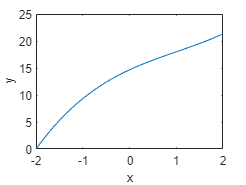


y = zeros(41, 1);
x = -2:0.1:2;

for i = 1:1:41
    y(i) = integral(f1, -2, x(i));
end
y;

plot(x, y)
xlabel("x")
ylabel("y")

### 2.6 F)

Utwórz typ danych tabelaryczny (`table`) zawierający dane jak na rysunku poniżej. Wyeksportuj dane z tabeli do pliku CSV. Wskazówka – sprawdź w systemie pomocy jak definiować nazwy kolumn oraz wierszy. Liczby do tabeli wygeneruj losowo. Skorzystaj z polecenia `writetable`

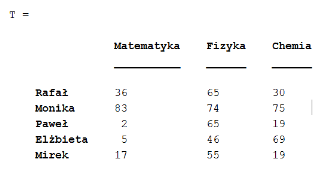

r1 = randi(100,5, 1);
r2 = randi(100,5, 1);
r3 = randi(100,5, 1);

T = table([r1],[r2], [r3],'VariableNames',{'Matematyka', 'Fizyka','Chemia'}, 'RowNames', {'Rafał';'Monika';'Paweł';'Elżbieta';'Mirek'})

T = 5×3 table
                Matematyka    Fizyka    Chemia
                __________    ______    ______

    Rafał           34          39        95  
    Monika          91          25        96  
    Paweł           37          41        58  
    Elżbieta        12          10         6  
    Mirek           79          14        24  


writetable